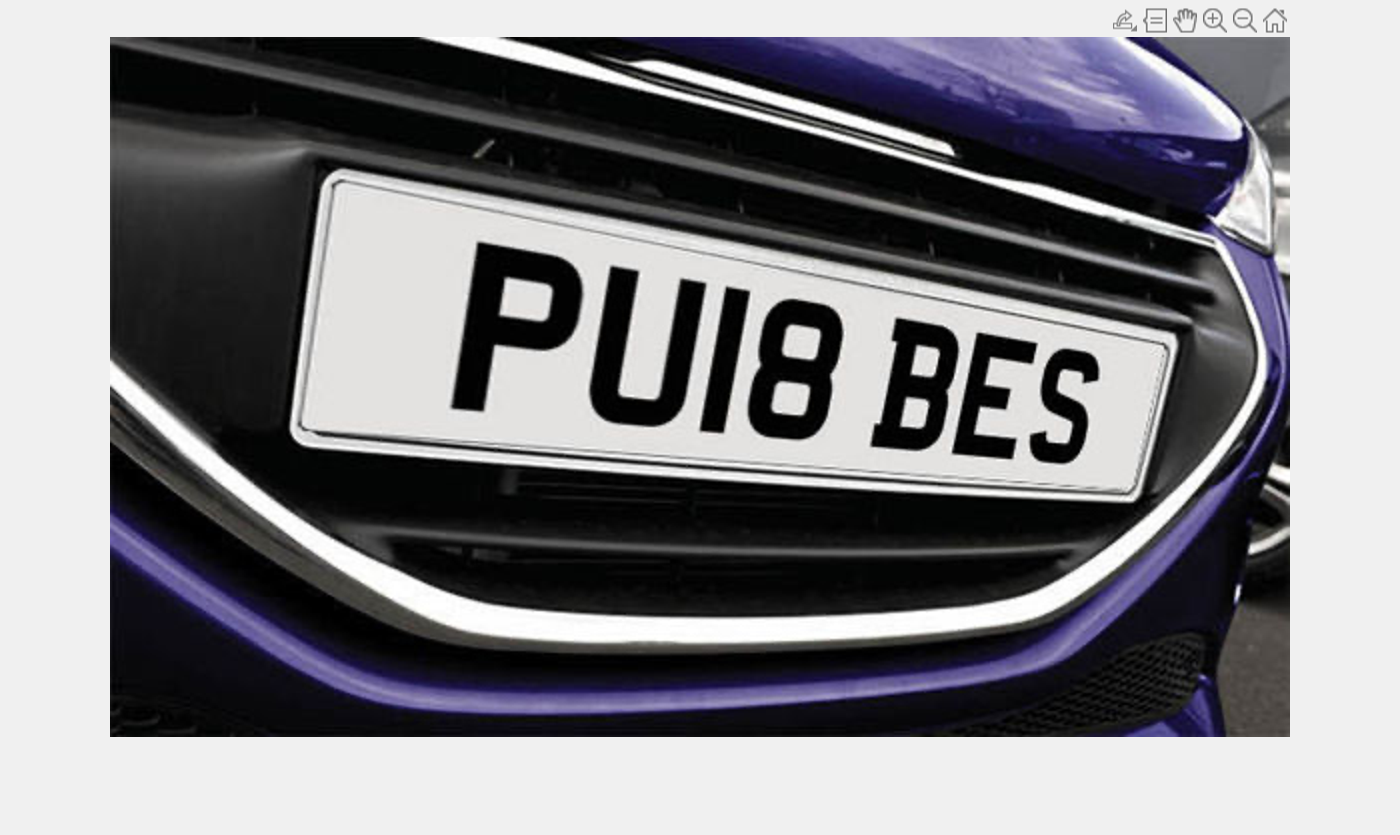

%% SECTION 1
clear all;
f = imread("car_images\Cars4.png");
f = imresize(f,2);
[f,rect] = imcrop(f); %user crops the image as best they can to the licence plate area

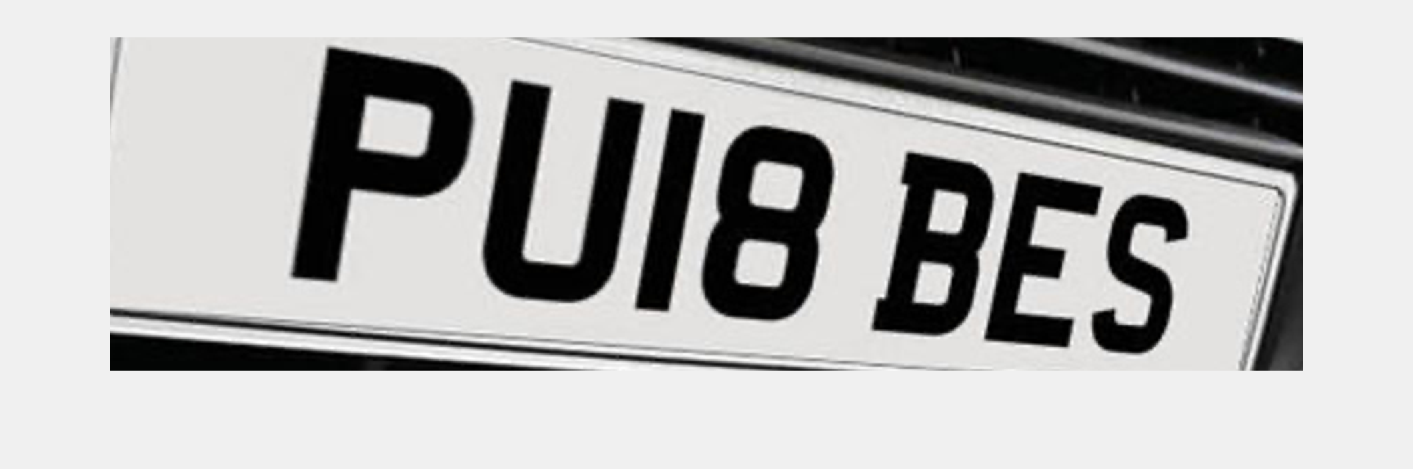


I = imresize(f,[500 NaN]); %resize so the number of rows of pixels is 500. 
%The number of columns is automatically calculated based on aspect ratio

imshow(I)


disp('SECTION 1 success')

SECTION 1 success


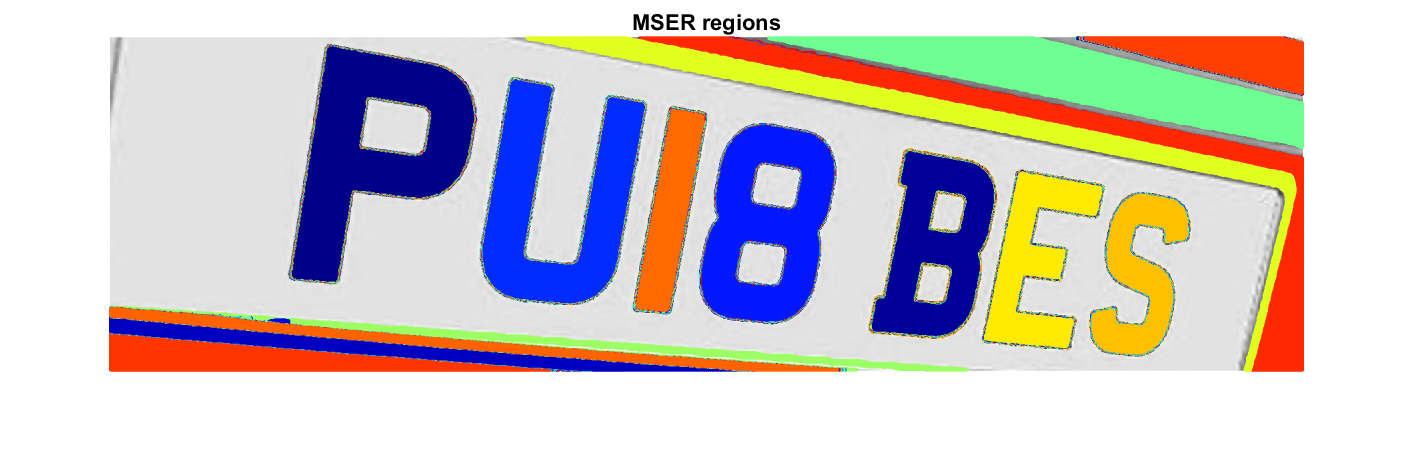

%% SECTION 2
I = im2gray(I); % for MSER to work image must be greyscale 

% Detect MSER regions. 
[mserRegions, mserConnComp] = detectMSERFeatures(I, ... 
    "RegionAreaRange",[10000 60000],"ThresholdDelta",5);

figure
imshow(I)
hold on
plot(mserRegions, "showPixelList", true,"showEllipses",false)
title("MSER regions")
hold off

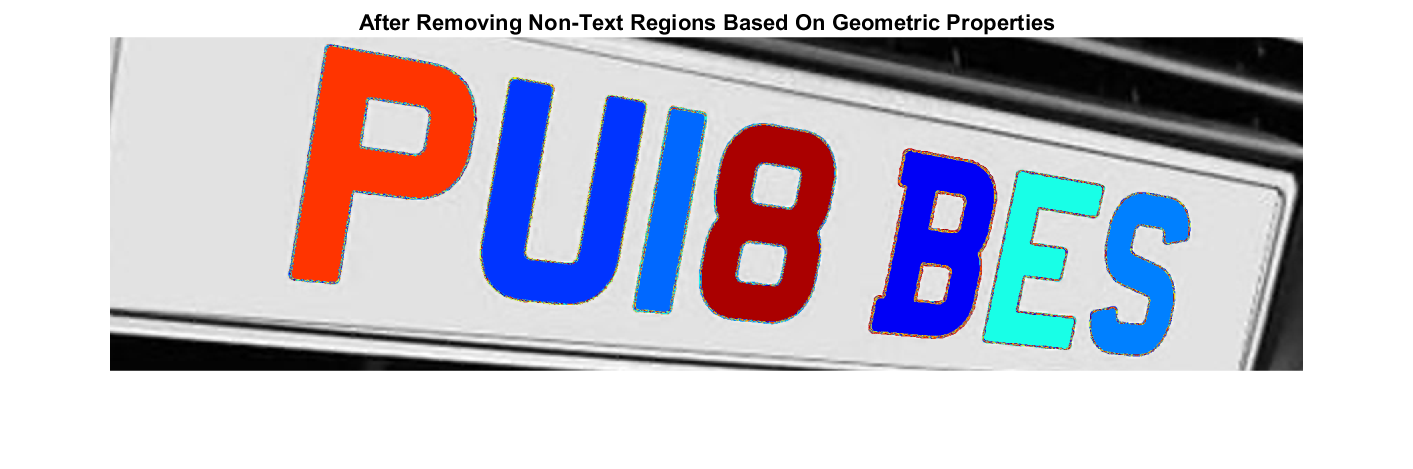


% Use regionprops (region properties) to measure MSER properties
mserStats = regionprops(mserConnComp, "BoundingBox", "Eccentricity", ...
    "Solidity", "Extent", "Euler", "Image");

% Compute the aspect ratio using bounding box data.
bbox = vertcat(mserStats.BoundingBox);
w = bbox(:,3);
h = bbox(:,4);
aspectRatio = w./h;

% Threshold the data to determine which regions to remove. These thresholds
% may need to be tuned for other images.
filterIdx = aspectRatio' > 3; 
filterIdx = filterIdx | [mserStats.Eccentricity] > .995 ;
filterIdx = filterIdx | [mserStats.Solidity] < .3;
filterIdx = filterIdx | [mserStats.Extent] < 0.2 | [mserStats.Extent] > 0.9;
filterIdx = filterIdx | [mserStats.EulerNumber] < -4;

% Remove regions
mserStats(filterIdx) = [];
mserRegions(filterIdx) = [];

% Show remaining regions
figure
imshow(I)
hold on
plot(mserRegions, "showPixelList", true,"showEllipses",false)
title("After Removing Non-Text Regions Based On Geometric Properties")
hold off


disp('SECTION 2 success')

SECTION 2 success


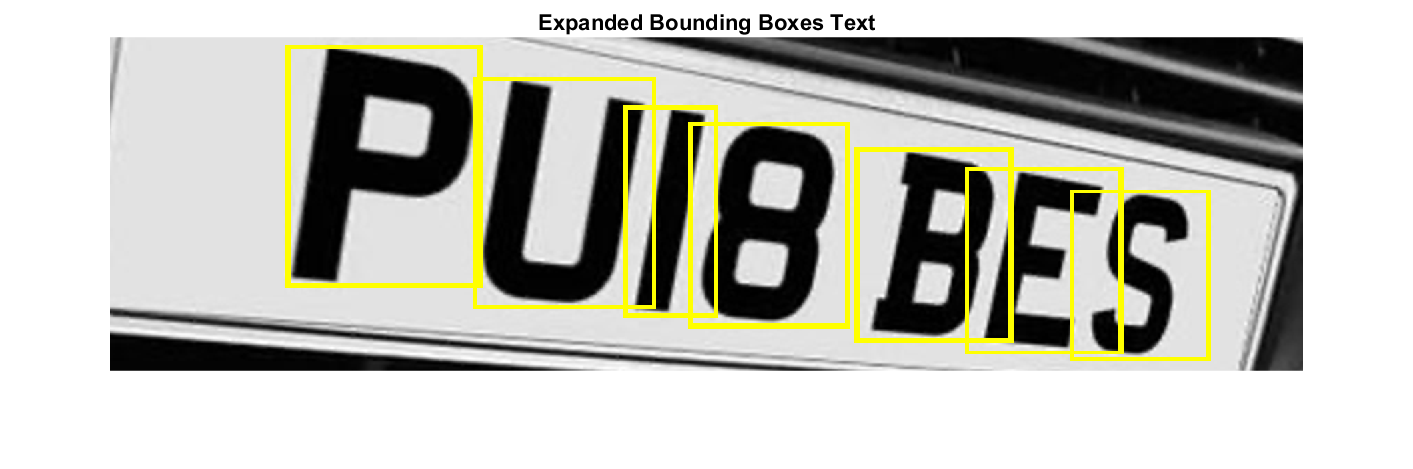

%% SECTION 3

% Get bounding boxes for all the regions
bboxes = vertcat(mserStats.BoundingBox);

% Convert from the [x y width height] bounding box format to the [xmin ymin
% xmax ymax] format for convenience.
xmin = bboxes(:,1);
ymin = bboxes(:,2);
xmax = xmin + bboxes(:,3) - 1;
ymax = ymin + bboxes(:,4) - 1;

% Expand the bounding boxes by a small amount.
expansionAmount = 0.02;
xmin = (1-expansionAmount) * xmin;
ymin = (1-expansionAmount) * ymin;
xmax = (1+expansionAmount) * xmax;
ymax = (1+expansionAmount) * ymax;

% Clip the bounding boxes to be within the image bounds
xmin = max(xmin, 1);
ymin = max(ymin, 1);
xmax = min(xmax, size(I,2));
ymax = min(ymax, size(I,1));

% Show the expanded bounding boxes
expandedBBoxes = [xmin ymin xmax-xmin+1 ymax-ymin+1];
IExpandedBBoxes = insertShape(I,"rectangle",expandedBBoxes,"LineWidth",3);

figure
imshow(IExpandedBBoxes)
title("Expanded Bounding Boxes Text")


disp('SECTION 3 success')

SECTION 3 success


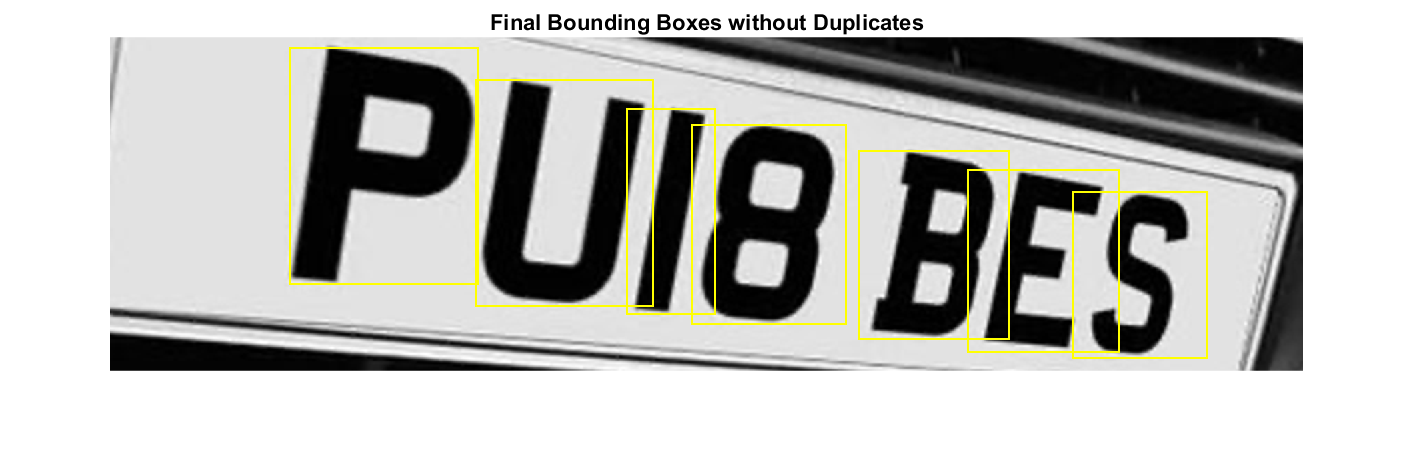

%% SECTION 4: Remove duplicate bounding boxes

% Initialize an empty array to store indices of unique bounding boxes
uniqueIndices = [];

% Calculate the area of each bounding box
areas = (xmax - xmin + 1) .* (ymax - ymin + 1);

% Iterate over each bounding box
for i = 1:size(expandedBBoxes, 1)
    % Flag to indicate if current bounding box is unique
    isUnique = true;
    
    % Iterate over already identified unique bounding boxes
    for j = 1:length(uniqueIndices)
        % Calculate intersection area
        x_overlap = max(0, min(xmax(i), xmax(uniqueIndices(j))) - max(xmin(i), xmin(uniqueIndices(j))));
        y_overlap = max(0, min(ymax(i), ymax(uniqueIndices(j))) - max(ymin(i), ymin(uniqueIndices(j))));
        intersection_area = x_overlap * y_overlap;
        
        % Calculate area ratio (intersection over min area)
        area_ratio = intersection_area / min(areas(i), areas(uniqueIndices(j)));
        
        % If area ratio is above a threshold, consider the bounding box duplicate
        if area_ratio > 0.5 % Adjust threshold as needed
            isUnique = false;
            break;
        end
    end
    
    % If current bounding box is unique, add its index to uniqueIndices
    if isUnique
        uniqueIndices = [uniqueIndices, i];
    end
end

% Extract unique bounding boxes
uniqueBBoxes = expandedBBoxes(uniqueIndices, :);

% Show the final bounding boxes after removing duplicates
IFinalBBoxes = insertShape(I, "rectangle", uniqueBBoxes, "LineWidth", 3);

figure
imshow(IFinalBBoxes)
title("Final Bounding Boxes without Duplicates")


disp('SECTION 4 success')

SECTION 4 success


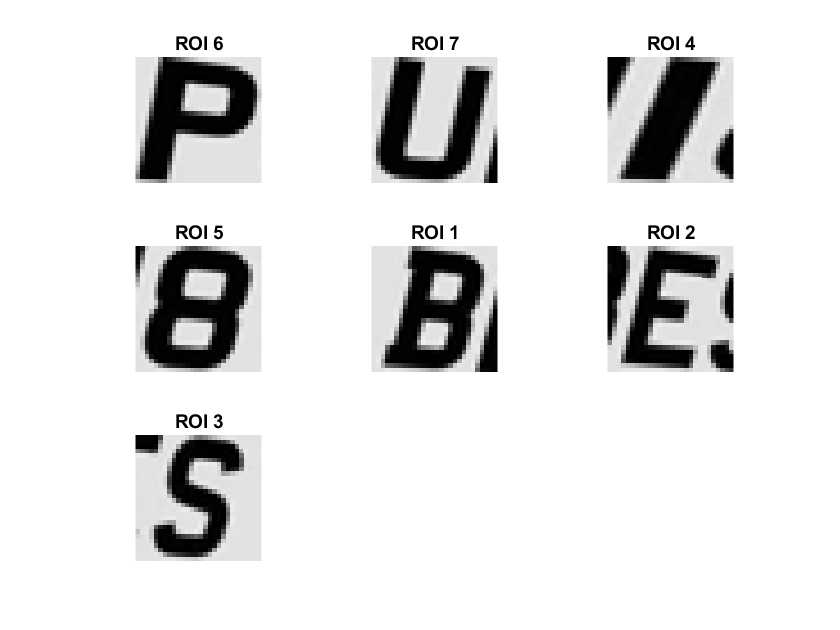

%% SECTION 5

% Assuming you have the image (I) and the bounding boxes (uniqueBBoxes)

% Initialize cell array to store individual letter ROIs and their corresponding bounding boxes
letterROIs = cell(size(uniqueBBoxes, 1), 1);
orderedBBoxes = uniqueBBoxes; % Copy bounding boxes for sorting

% Sort bounding boxes by their x-coordinates (xmin)
[~, order] = sort(orderedBBoxes(:, 1));
orderedBBoxes = orderedBBoxes(order, :);

% Iterate over each bounding box
for i = 1:size(orderedBBoxes, 1)
    % Extract ROI using bounding box coordinates
    xmin = orderedBBoxes(i, 1);
    ymin = orderedBBoxes(i, 2);
    width = orderedBBoxes(i, 3);
    height = orderedBBoxes(i, 4);
    roi = imcrop(I, [xmin, ymin, width, height]);
    
    % Preprocess ROI (e.g., resize, binarize, etc.)
    % Example: resize ROI to a fixed size (e.g., 28x28 pixels) for character recognition
    roi = imresize(roi, [28, 28]);
    %roi = imbinarize(roi); % Binarize the image
    
    % Store preprocessed ROI
    letterROIs{i} = roi;
end

% Create a subplot grid
numRows = ceil(sqrt(length(letterROIs))); % Determine number of rows
numCols = ceil(length(letterROIs) / numRows); % Determine number of columns
figure;

% Display each ROI in a subplot
for i = 1:length(letterROIs)
    % Create subplot with adjusted aspect ratio
    subplot(numRows, numCols, i);
    
    % Display ROI
    imshow(letterROIs{i});
    
    % Adjust aspect ratio of subplot to match ROI
    aspectRatio = size(letterROIs{i}, 2) / size(letterROIs{i}, 1);
    daspect([1 aspectRatio 1]);
    
    % Set title
    title(['ROI ' num2str(order(i))]); % Display original order
end